clc;
close all;
clear variables;

### Simulacija

Parametri simulacije

sim_file_name = "buck_boost_DCDC_sim_3";
open_system(sim_file_name);

sim_duration = 1; % sec
time_step = 1e-4;

Propusni opseg za nelinearne kontrolere

w0 = 125; % rad/s
w_diff = w0 * 20; % da bude dovoljno van propusnog opsega
w_prefiltar = 0.5 * w0; % odokativno

Linearni kontroler

% K_pracenje_ref = kontroler_pracenje_reference_foo();
[K_znf, ~] = ziegler_nichols_frekvencijski_foo();

[Kp, Ti, Td, Tf] = PID_oblik_foo(K_znf);
Tt = 1e-3; % s
[G, ~, ~, ~, ue] = linearizacija();
s = tf('s');
% Kp*2, Ti*1, Td*1.5 
% Kp*2, Ti*0.5, Td*2
Kp = Kp*2

Kp = -0.0121

Ti = Ti*0.5

Ti = 0.0090

Td = Td * 2

Td = 0.0090

Tf = Td / 20;
Kont = Kp *(1 + 1/Ti/s + Td*s/(Tf*s + 1));
% figure()
% margin(Kont*G)

Feedback linearizacija

p = 3*w0; %trostruki pol da bi prop opseg bio w0

k_i = p^3;
k_0 = 3*p^2;
k_1 = 3*p;
K_fl = [k_i,k_0,k_1];

subsystem_name = "/Feedback linearizacija";

feedback_linearizacija_foo(sim_file_name, subsystem_name)

Sliding mode control

beta = 10000;
p = 2*w0;
K_0 = 2*p;
K_i = p^2;
K_smc = [K_i, K_0];

K_smc_0 = [0, K_smc];

subsystem_name = "/Klizno upravljanje";
sliding_mode_control_foo(sim_file_name, subsystem_name, K_smc)


Boundry layer sliding mode control

phi = beta / 1 / p; % mora veliko zbog suma
subsystem_name = "/Klizno upravljanje sa granicnim slojem";
sliding_mode_control_foo(sim_file_name, subsystem_name, K_smc)

Fuzzy logic controler

Kd_cap = 1/2700; %nemoj dirati da ne bi uslo u zasicenje
Ku_cap =Kp*Td/Kd_cap*1.2;
Kp_cap =Kp/Ku_cap;
Ki_cap =Kp/Ti/Ku_cap*1.5;

Parametri sistema

[L, R, C, E, x_2e] = nominalni_parametri();

Referenca i poremecaj

t_ref = [1/6, 2/6, 3/6, 4/6 ] * sim_duration;
step_ref = [0.05, -0.05, -0.05, 0.05] * x_2e;

t_poremecaj = [5/6] * sim_duration;
step_poremecaj = [1/3] * E;

Opsti parametri kontrolera

R_dot_enable = 0;
prefiltar_enable = 1;
noise_enable = 1;

sigma_noise = 0.02 * abs(x_2e);


% "smc", "fbl", "bl smc", "lin", "fuzzy"
ime_kontrolera_array = ["lin", "fbl", "bl smc", "fuzzy"];


Simulacija



for i = 1:length(ime_kontrolera_array)
    ime_kontrolera = ime_kontrolera_array(i);
    out(i) = sim(sim_file_name);
    
end

### Crtanje

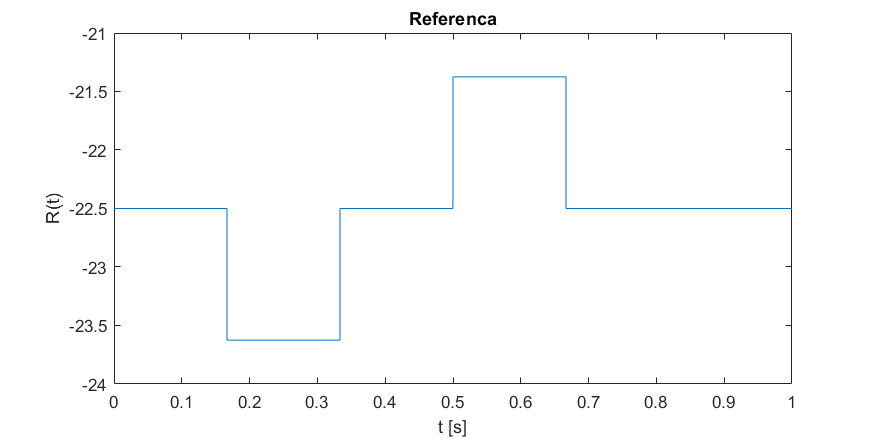

main_plot_linewidth = 1;
auxiliary_plot_linewidth = 0.5;
fig_vector = [10, 10, 700, 350];


fig = figure();

set(gcf,'Position', fig_vector)
plot(out(1).ref_no_filter)
title("Referenca")
xlabel("t [s]")
ylabel("R(t)")

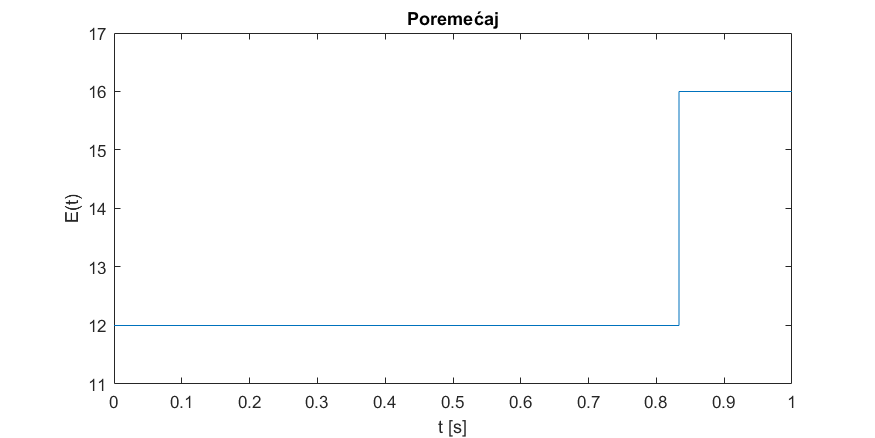

fig = figure();

set(gcf,'Position', fig_vector)
plot(out(1).poremecaj + E)
title("Poremećaj")
xlabel("t [s]")
ylabel("E(t)")
ylim([11 17])

#### Izlaz

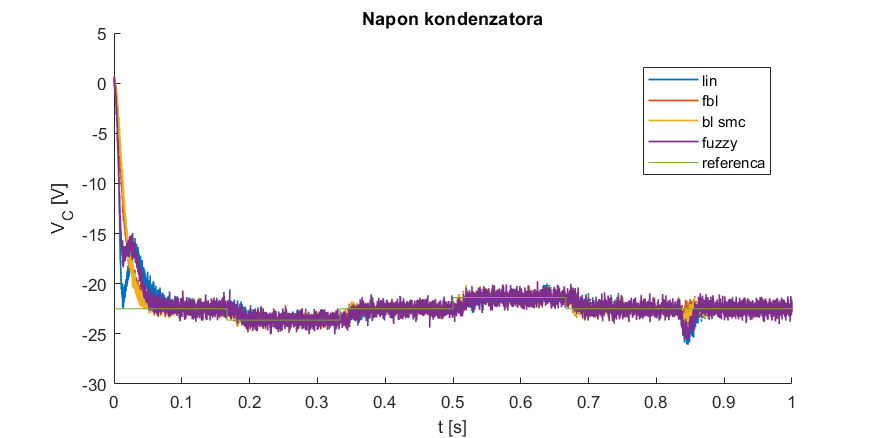

y_oznaka = "V_C [V]";
naslov = "Napon kondenzatora";
ref_flg = false;
poremecaj_flg = false;

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_celog_signala(fig, naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);
    labels{i} = ime_kontrolera_array(i);
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), 0, sim_duration);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

Prelazak ka nominalnom rezimu rada

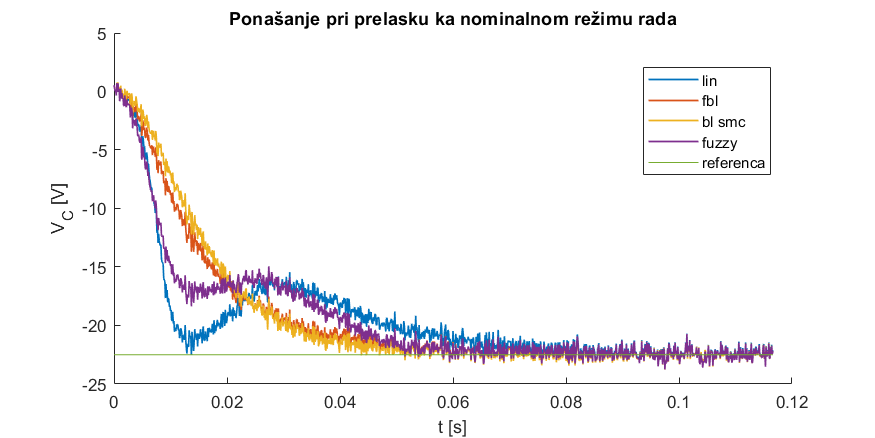

naslov = "Ponašanje pri prelasku ka nominalnom režimu rada";
t_start = 0;
t_end = 0.7 * t_ref(1);


plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), t_start, t_end);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

Odziv na referencu

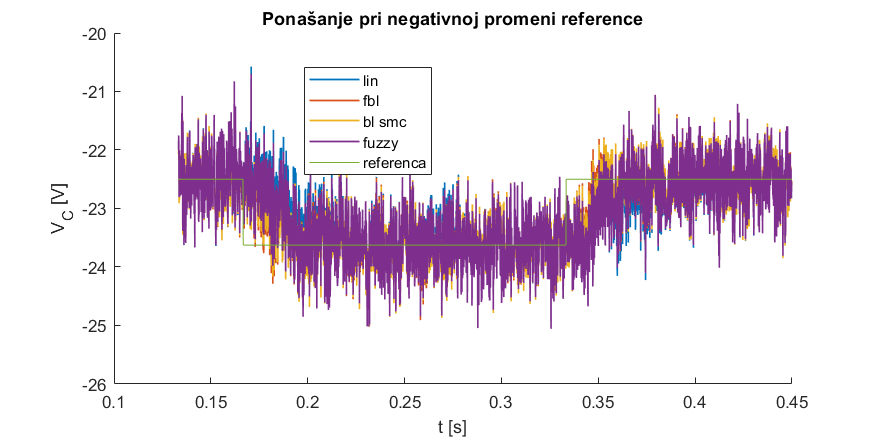

naslov = "Ponašanje pri negativnoj promeni reference";
t_start = 0.8 * t_ref(1);
t_end = 0.9 * t_ref(3);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), t_start, t_end);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

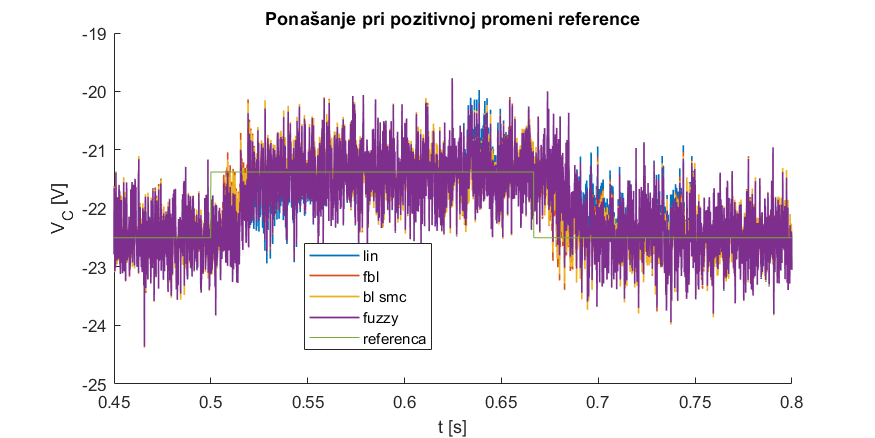

naslov = "Ponašanje pri pozitivnoj promeni reference";
t_start = 0.9 * t_ref(3);
t_end = 1.2 * t_ref(4);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), t_start, t_end);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

Poremecaj

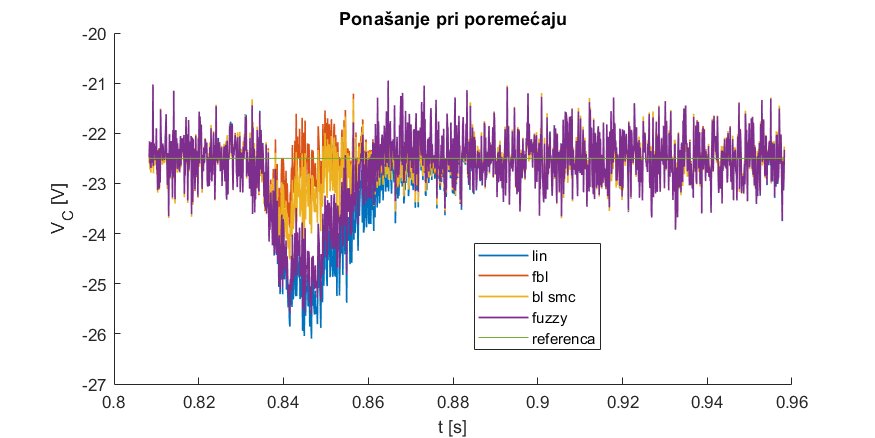

naslov = "Ponašanje pri poremećaju";
t_start = 0.97 * t_poremecaj(1);
t_end = 1.15 * t_poremecaj(1);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), t_start, t_end);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

#### Upravljanje

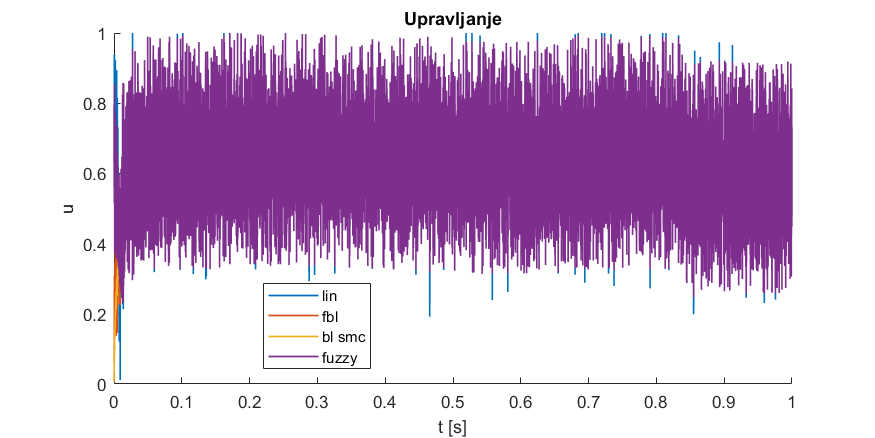

y_oznaka = "u";
naslov = "Upravljanje";
target_timeseries = out.upravljanje;
ref_flg = false;
poremecaj_flg = false;

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_celog_signala(fig, naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);
   labels{i} = ime_kontrolera_array(i);
end
legend(plts, labels, 'Location', 'best')

Prelazak ka nominalnom rezimu rada

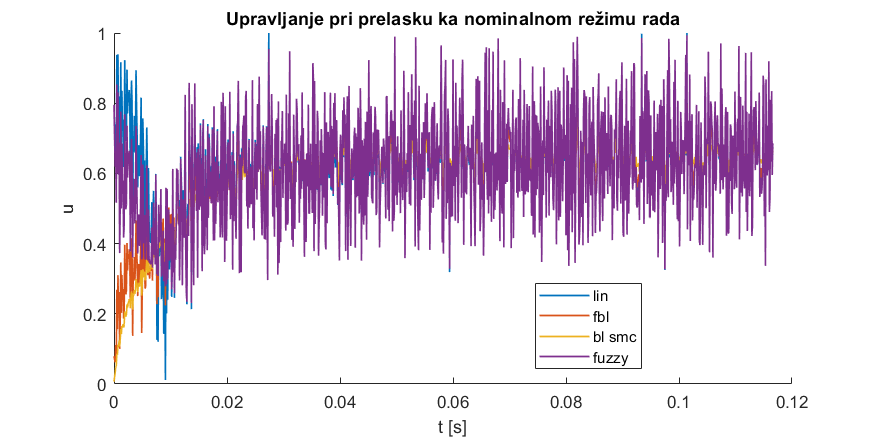

naslov = "Upravljanje pri prelasku ka nominalnom režimu rada";
t_start = 0;
t_end = 0.7 * t_ref(1);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end
legend(plts, labels, 'Location', 'best')

Odziv na referencu

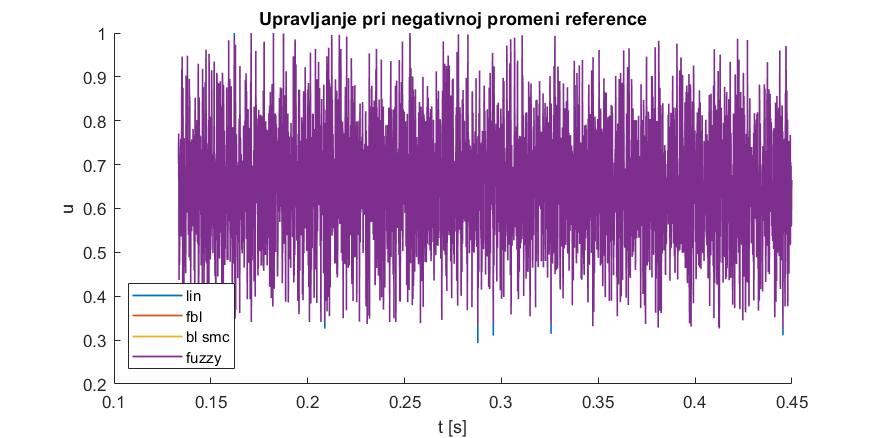

naslov = "Upravljanje pri negativnoj promeni reference";
t_start = 0.8 * t_ref(1);
t_end = 0.9 * t_ref(3);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end
legend(plts, labels, 'Location', 'best')

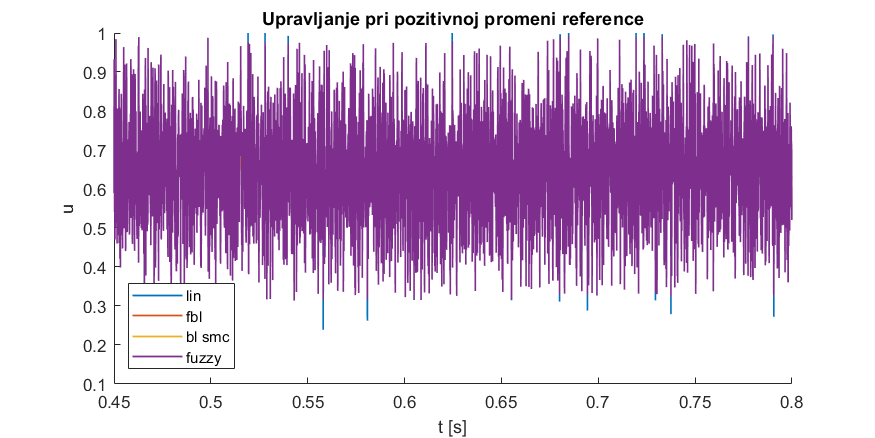

naslov = "Upravljanje pri pozitivnoj promeni reference";

t_start = 0.9 * t_ref(3);
t_end = 1.2 * t_ref(4);
plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end
legend(plts, labels, 'Location', 'best')

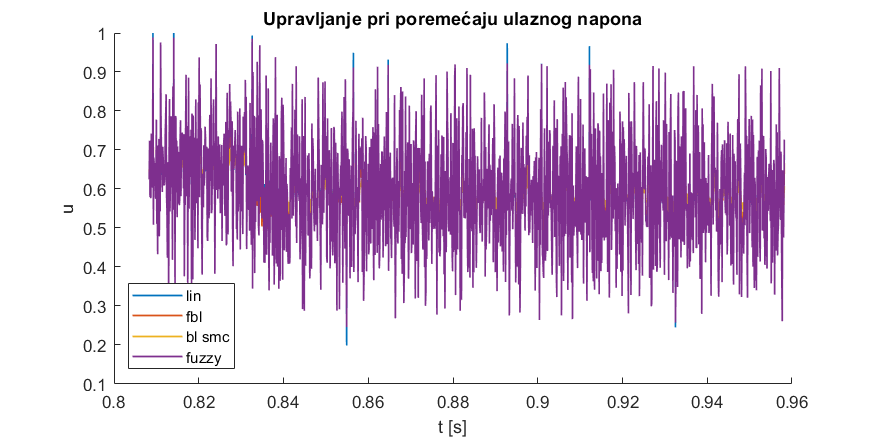

naslov = "Upravljanje pri poremećaju ulaznog napona";
t_start = 0.97 * t_poremecaj(1);
t_end = 1.15 * t_poremecaj(1);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end
legend(plts, labels, 'Location', 'best')

#### Fazni portret

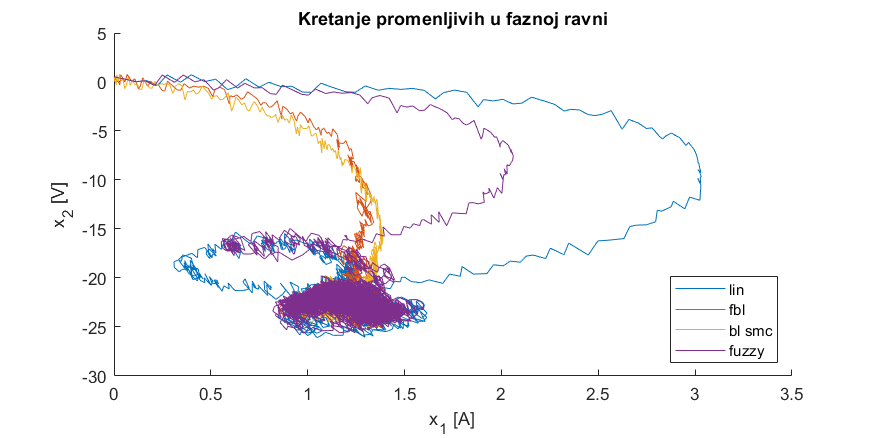

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    plts(i) = plot(out(i).x1.Data, out(i).x2.Data);
    labels{i} = ime_kontrolera_array(i);
end
title("Kretanje promenljivih u faznoj ravni")
xlabel("x_1 [A]")
ylabel("x_2 [V]")
legend(plts, labels, 'Location', 'best')

### Struja kalema

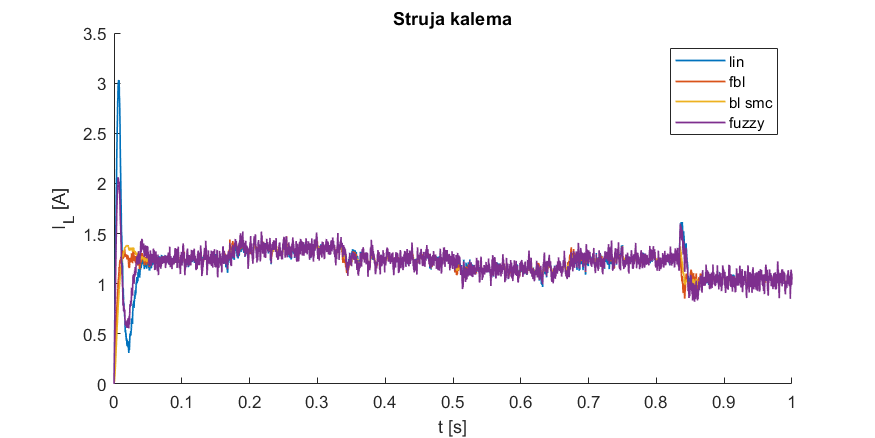

y_oznaka = "I_L [A]";
naslov = "Struja kalema";
target_timeseries = out.x1;
ref_flg = false;
poremecaj_flg = false;

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x1;
    plts(i) = crtanje_celog_signala(fig, naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);
   labels{i} = ime_kontrolera_array(i);
end
legend(plts, labels, 'Location', 'best')

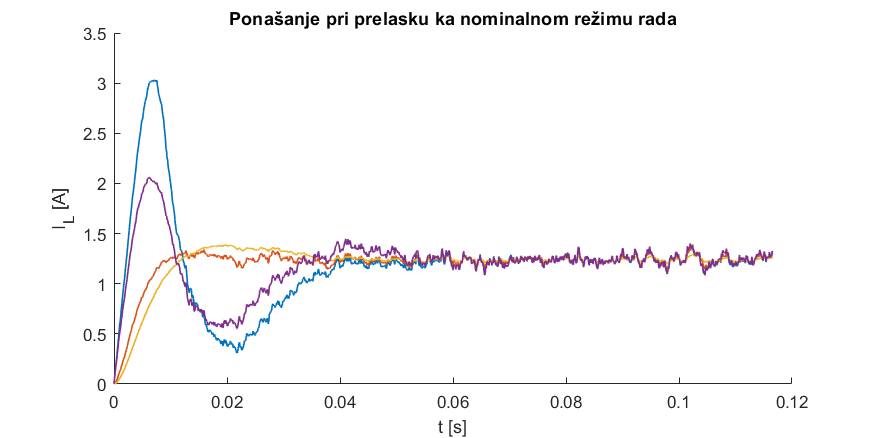

naslov = "Ponašanje pri prelasku ka nominalnom režimu rada";
t_start = 0;
t_end = 0.7 * t_ref(1);


plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x1;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end

Odziv na referencu

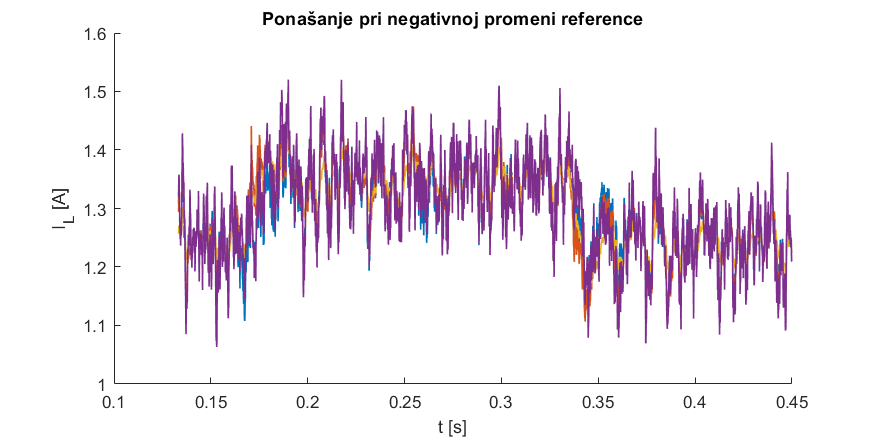

naslov = "Ponašanje pri negativnoj promeni reference";
t_start = 0.8 * t_ref(1);
t_end = 0.9 * t_ref(3);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x1;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end

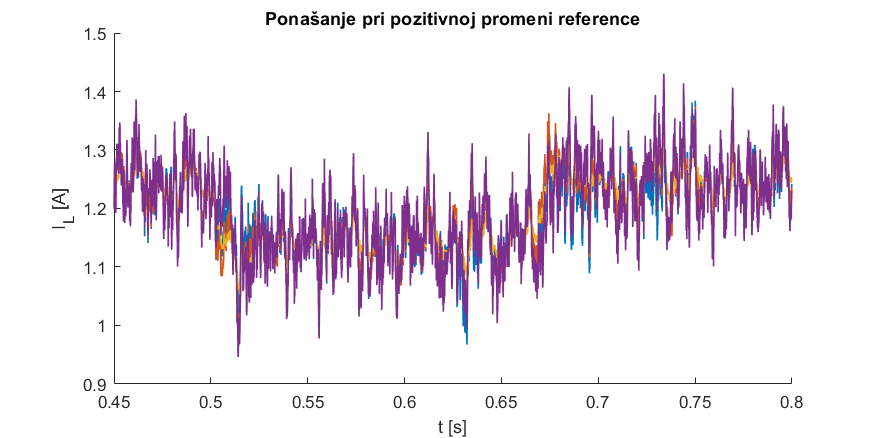


naslov = "Ponašanje pri pozitivnoj promeni reference";
t_start = 0.9 * t_ref(3);
t_end = 1.2 * t_ref(4);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x1;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end

Poremecaj

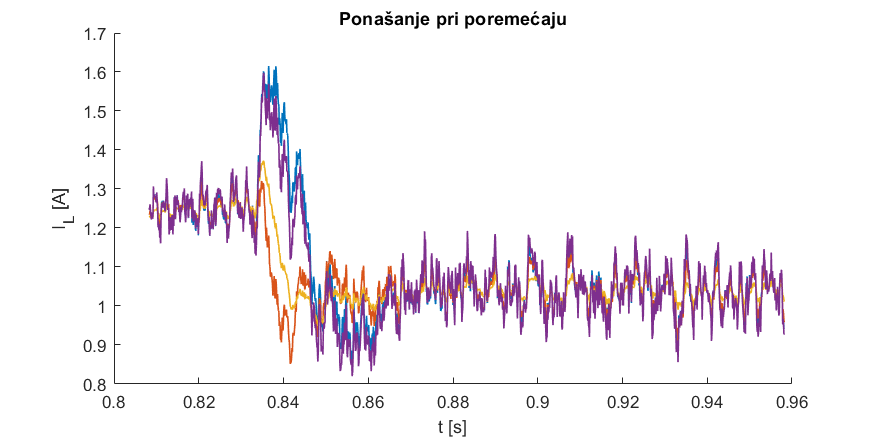

naslov = "Ponašanje pri poremećaju";
t_start = 0.97 * t_poremecaj(1);
t_end = 1.15 * t_poremecaj(1);

plts = [];
labels = {};

fig = figure();
set(gcf,'Position', fig_vector)
hold on;
for i = 1:length(ime_kontrolera_array)
    target_timeseries = out(i).x1;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = ime_kontrolera_array(i);
end